# GeoPlotWaves 

Author: M. Noyce

This program takes the processed wave height and wave period time series from TimeAnalysisAllSeries.mlx, cross references their times with the logged GPS times for each buoy and plot them on a geographic map. Program starts by extracting raw geographic data 

## Import Raw Geographical Data 

projectdir = "C:\Users\uctsh\Documents\MATLAB\GPSData\";


## SB04 GPS and Wave Parameter Preprocessing

gpsfileSB04 = fullfile(projectdir, "SB04_GPS_Local.txt"); 
%GPS Data
SB04 = readtable(gpsfileSB04);
Device = 4*ones(height(SB04), 1); 
SB04 = addvars(SB04, Device, 'before', "TimeUTC"); 
%Filter out null GPS values
SB04 = SB04(SB04.("Latitude") < 0.0, :);

%Wave Parameters 
waveParamSB04 = readtable("SB04_Wave_Parameters_Heave.txt");
%Note 17:09 20/07/2022 was defined as sample no 1

%Add sample no. to wave parameters
waveParamSB04.sampleNo = (1:height(waveParamSB04)).'

waveParamSB04 = 125×6 table
        DateTimeUTC          Hm0       Tm01     Hm0_upper    Hm0_lower    sampleNo
    ____________________    ______    ______    _________    _________    ________

    20-Jul-2022 17:09:05     1.198    17.133     1.6265       0.95596         1   
    20-Jul-2022 17:51:08    1.2853    16.698     1.7449        1.0256         2   
    20-Jul-2022 18:33:04    1.4237    17.359     1.9329         1.136         3   
    20-Jul-2022 19:15:07    1.7029    17.392     2.3119        1.3588         4   
    20-Jul-2022 19:57:09    1.8174    17.044     2.4674        1.4502         5   
    20-Jul-2022 20:39:05    2.1396    17.204     2.9048        1.7073         6   
    20-Jul-2022 21:21:06    2.1685    17.262      2.944        1.7303         7   
    20-Jul-2022 22:0


%Remove all null wave parameters
waveParamSB04 = rmmissing(waveParamSB04);

%Remove all samples before sample no 1
SB04 = SB04(SB04.DateTimeUTC > datetime(2022, 07, 20, 17, 08, 00), :);

%Create array of interpolated GPS Data (midpoint method ) TODO: More
%advanced method

GPSinter = zeros( height(SB04)/2, 2);
j = 1; %inner loop counter

for i = 2 : height(SB04)
    if SB04.timeSeriesCount(i) ==  SB04.timeSeriesCount(i-1)
        GPSinter(j, 1) = (SB04.Latitude(i) + SB04.Latitude(i - 1))/2; 
        GPSinter(j, 2) = (SB04.Longitude(i) + SB04.Longitude(i - 1))/2;
        j = j +1; 
    end
end

%if uneven sampling sessions
if (GPSinter(end, 1) == 0)
    GPSinter(end, :) = [];
end


%Add interpolated values to wave parameter table:
waveParamSB04 = addvars(waveParamSB04, GPSinter(:, 1), GPSinter(:, 2), 'NewVariableNames', {'Latitude','Longitude'}); 
waveParamSB04 = convertvars(waveParamSB04,{'Latitude','Longitude'},'double');

## SB06 GPS and Wave Parameter Preprocessing

gpsfileSB06 = fullfile(projectdir, "SB06_GPS_Local.txt"); 
%GPS Data
SB06 = readtable(gpsfileSB06);
Device = 6*ones(height(SB06), 1); 
SB06 = addvars(SB06, Device, 'before', "TimeUTC"); 
%Filter out null GPS values
SB06 = SB06(SB06.("Latitude") < 0.0, :);

%Wave Parameters 
waveParamSB06 = readtable("SB06_Wave_Parameters_Heave.txt");
%Note 17:09 20/07/2022 was defined as sample no 1

%Add sample no. to wave parameters
waveParamSB06.sampleNo = (1:height(waveParamSB06)).'

waveParamSB06 = 91×6 table
        DateTimeUTC          Hm0       Tm01     Hm0_upper    Hm0_lower    sampleNo
    ____________________    ______    ______    _________    _________    ________

    20-Jul-2022 19:28:23    1.4258    17.942     1.9357       1.1377          1   
    20-Jul-2022 20:10:03    1.6207    18.088     2.2004       1.2933          2   
    20-Jul-2022 20:51:42    1.7134    17.905     2.3262       1.3672          3   
    20-Jul-2022 21:33:14    2.1986    17.773      2.985       1.7544          4   
    20-Jul-2022 22:14:53    2.1257      17.2      2.886       1.6962          5   
    20-Jul-2022 22:56:32    2.5748    17.314     3.4956       2.0546          6   
    20-Jul-2022 23:38:02    2.1584    17.186     2.9304       1.7223          7   
    21-Jul-2022 00:19


%Remove all null wave parameters
waveParamSB06 = rmmissing(waveParamSB06);

waveParamSB06 = waveParamSB06(waveParamSB06.DateTimeUTC > datetime(2022, 07, 20, 19, 30, 00), :);

%Remove all samples before sample no 1
SB06 = SB06(SB06.DateTimeUTC > datetime(2022, 07, 20, 19, 30, 00), :);

%Create array of interpolated GPS Data (midpoint method ) TODO: More
%advanced method

GPSinter2 = zeros( ceil(height(SB06)/2), 2);
j = 1; %inner loop counter

for i = 2 : height(SB06)
    if SB06.timeSeriesCount(i) ==  SB06.timeSeriesCount(i-1)
        GPSinter2(j, 1) = (SB06.Latitude(i) + SB06.Latitude(i - 1))/2; 
        GPSinter2(j, 2) = (SB06.Longitude(i) + SB06.Longitude(i - 1))/2;
        j = j +1; 
    end
end

%if uneven sampling sessions
if (GPSinter2(end, 1) == 0)
    GPSinter2(end, :) = [];
end

GPSinter2(end, :) = [];

%Add interpolated values to wave parameter table:
waveParamSB06 = addvars(waveParamSB06, GPSinter2(:, 1), GPSinter2(:, 2), 'NewVariableNames', {'Latitude','Longitude'}); 
waveParamSB06 = convertvars(waveParamSB06,{'Latitude','Longitude'},'double');

## GPS Plot Data 

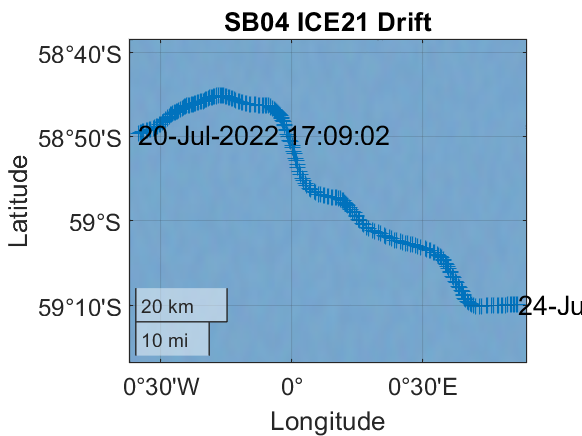

geoplot(SB04.("Latitude"), SB04.("Longitude"), 'Marker', '+')
title("SB04 ICE21 Drift")
text(SB04.("Latitude")(end), SB04.("Longitude")(end), string(SB04.("DateTimeUTC")(end)))
text(SB04.("Latitude")(1), SB04.("Longitude")(1), string(SB04.("DateTimeUTC")(1)))
geobasemap colorterrain
hold off

% geoplot(SB06.("Latitude"), SB06.("Longitude"), 'Marker', '+')
% title("SB06 ICE00 Drift")
% text(SB06.("Latitude")(end), SB06.("Longitude")(end), string(SB06.("DateTimeUTC")(end)))
% text(SB06.("Latitude")(1), SB06.("Longitude")(1), string(SB06.("DateTimeUTC")(1)))
% geobasemap colorterrain

## Plot Individual

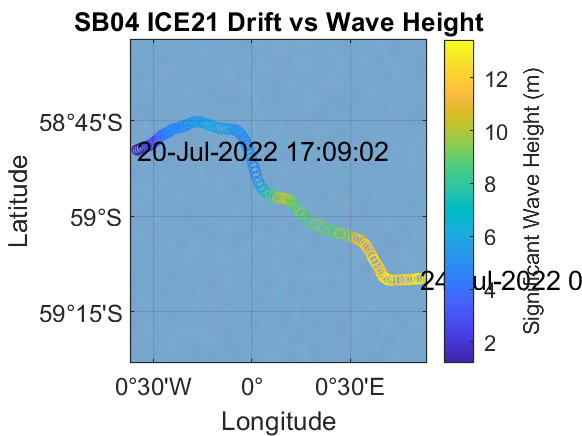

geoscatter(GPSinter(:, 1), GPSinter(:, 2), 15, waveParamSB04.Hm0);
title("SB04 ICE21 Drift vs Wave Height")
text(GPSinter(end, 1), GPSinter(end, 2), string(SB04.("DateTimeUTC")(end)))
text(GPSinter(1, 1), GPSinter(1, 2), string(SB04.("DateTimeUTC")(1)))
geobasemap colorterrain
c = colorbar;
c.Label.String = 'Significant Wave Height (m)';

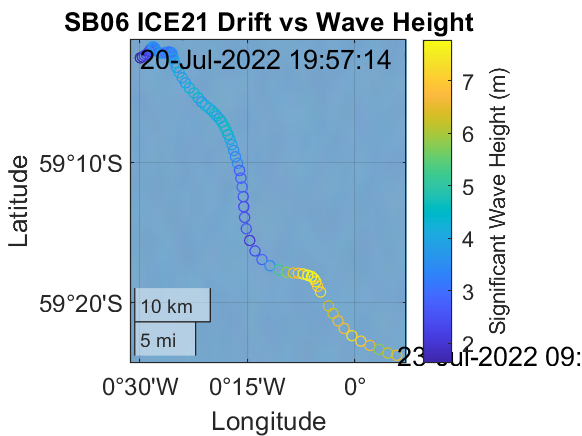



geoscatter(GPSinter2(:, 1), GPSinter2(:, 2), 15, waveParamSB06.Hm0);
title("SB06 ICE21 Drift vs Wave Height")
text(GPSinter2(end, 1), GPSinter2(end, 2), string(SB06.("DateTimeUTC")(end)))
text(GPSinter2(1, 1), GPSinter2(1, 2), string(SB06.("DateTimeUTC")(1)))
geobasemap colorterrain
c = colorbar;
c.Label.String = 'Significant Wave Height (m)';

## Plot combined

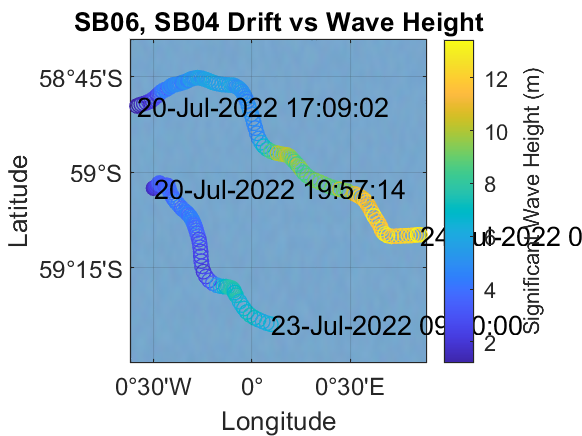

geoscatter(GPSinter(:, 1), GPSinter(:, 2), 30, waveParamSB04.Hm0);
text(GPSinter(end, 1), GPSinter(end, 2), string(SB04.("DateTimeUTC")(end)))
text(GPSinter(1, 1), GPSinter(1, 2), string(SB04.("DateTimeUTC")(1)))
hold on 
geoscatter(GPSinter2(:, 1), GPSinter2(:, 2), 30, waveParamSB06.Hm0);
text(GPSinter2(end, 1), GPSinter2(end, 2), string(SB06.("DateTimeUTC")(end)))
text(GPSinter2(1, 1), GPSinter2(1, 2), string(SB06.("DateTimeUTC")(1)))
hold on
title("SB06, SB04 Drift vs Wave Height")
geobasemap colorterrain
c = colorbar;
c.Label.String = 'Significant Wave Height (m)';
hold off